**Problema 10**

Subpunctul 1

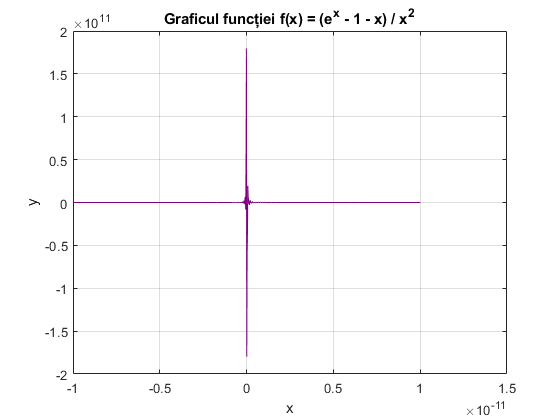

% Generez 1000 de puncte pe intervalul x ∈ [−10^(−11), 10^(−11)], pentru a vizualiza in detaliu comportamentul functiei in apropierea punctului 0
x = linspace(-10^(-11), 10^(-11), 1000); 

% Calculez valorile y=f(x)
y = (exp(x) - 1 - x) ./ (x.^2); 

plot(x, y, 'Color', [0.5 0 0.5], 'LineWidth', 0.5);
xlabel('x');
ylabel('y');
title('Graficul funcției f(x) = (e^x - 1 - x) / x^2');
grid on;

Se observa o eroare relativa mare pentru valorile lui x foarte apropiate de 0, intrucat atat numitorul, cat si numaratorul tind spre 0. 

O solutie, ar fi sa folosim o aproximare a functiei cu formula lui Taylor. Seria Taylor asociata functiei e^x in punctul 0 este:

e^x ≈ 1 + x + x^2/2! + x^3/3! + x^4/4! + ...

Asadar, functia aproximata devine:

f(x) ≈ ((1 + x + x^2/2! + x^3/3! +  ...) - 1 - x) / x^2 = x^2/2! / x^2 + x^3/3! / x^2

Subpunctul 2

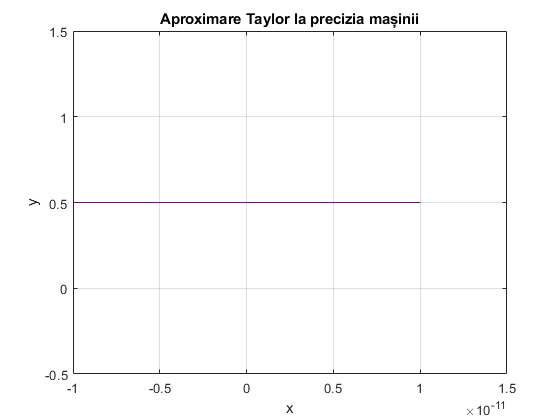


% Generez 1000 de puncte pe intervalul x ∈ [−10^(−11), 10^(−11)], pentru a vizualiza in detaliu comportamentul functiei in apropierea punctului 0
x = linspace(-10^(-11), 10^(-11), 1000); 

y = arrayfun(@custom_f_taylor, x); % metoda de calcul a lui f pentru |x| < 1 la precizia masinii

plot(x, y, 'Color', [0.5 0 0.5], 'LineWidth', 0.5);
xlabel('x');
ylabel('y');
title('Aproximare Taylor la precizia mașinii');
grid on;